folder_us = '..//..//Data//registration_data//Registration2025-11-11//Run-1-beamformed';
% save_folder = 'Registration2025-11-11//Run-1-tiffs';
files_us = dir(folder_us);
files_us = files_us(3:end);
load(fullfile(folder_us,files_us(end).name),'Trans','Receive')
load(fullfile(folder_us,files_us(1).name))
xs = ((-(Trans.numelements/2 -1):(Trans.numelements/2))-0.5)*Trans.spacingMm;
xs = xs(14:115);
fs=Receive(1).decimSampleRate;
dt = 1/fs;
ts = (0:(length(IQData)-1))*dt;
zs = 1.48*ts/2;
dx = xs(2) - xs(1);
dz = zs(2) - zs(1);
zmask = zs <10;
data = zeros(102,length(files_us)-1,845);

for i=1:(length(files_us)-1)
    load(fullfile(folder_us,files_us(i).name))
    if ~isnan(str2double(files_us(i).name(33:35)))
        num_label = files_us(i).name(33:35);
    elseif ~isnan(str2double(files_us(i).name(33:34)))
        num_label = files_us(i).name(33:34);
    else
        num_label = files_us(i).name(33);
    end

    index = str2num(num_label);



    % Bmode = uint16(20*log10(abs(IQData(zmask,:))+1) *65535/100);
    Bmode = 20*log10(abs(IQData(zmask,:))+1);

    % imagesc(xs,zs(zmask),Bmode)
    % colormap gray
    % xs
    % imwrite(Bmode, fullfile(save_folder,[num_label '.tif']), 'tif','Compression', 'none');
    data(:,index,:) = Bmode.';
end

pos_file = '..//..//Data//registration_data//US_PositionList_registration.pos';
jsonText = fileread(pos_file);
datastruct = jsondecode(jsonText);
pos_struct = datastruct.map.StagePositions.array;
% pos_struct(1).Label.scalar
positions = zeros(length(files_us)-1,2);
for i=1:(length(files_us)-1)
    positions(i,:) = pos_struct(i).DevicePositions.array.Position_um.array'/1000;
end

data1 = circshift(data,ceil(1/dz),3);

pos = cell(3,1);
pos{1} = positions(1:201,:);
pos{2} = positions(202:402,:);
pos{3} = positions(403:end,:);

data_cell = cell(3,1);
data_cell{1} = data1(:,1:201,:);
data_cell{2} = data1(:,202:402,:);
data_cell{3} = data1(:,403:603,:);

xs1 = xs;
ys1 = pos{1}(:,2).';
zs1 = zs(zmask);
% xs1 = reshape(xs,[102 1 1]);
% ys1 = reshape(pos{1}(:,2).',[1 201 1]);
% zs1 = reshape(zs(zmask),[1 1 845]);
% X = repmat(xs1,[1 201 845]);
% Y = repmat(ys1,[102 1 845]);
% Z = repmat(zs1,[102 201 1]);

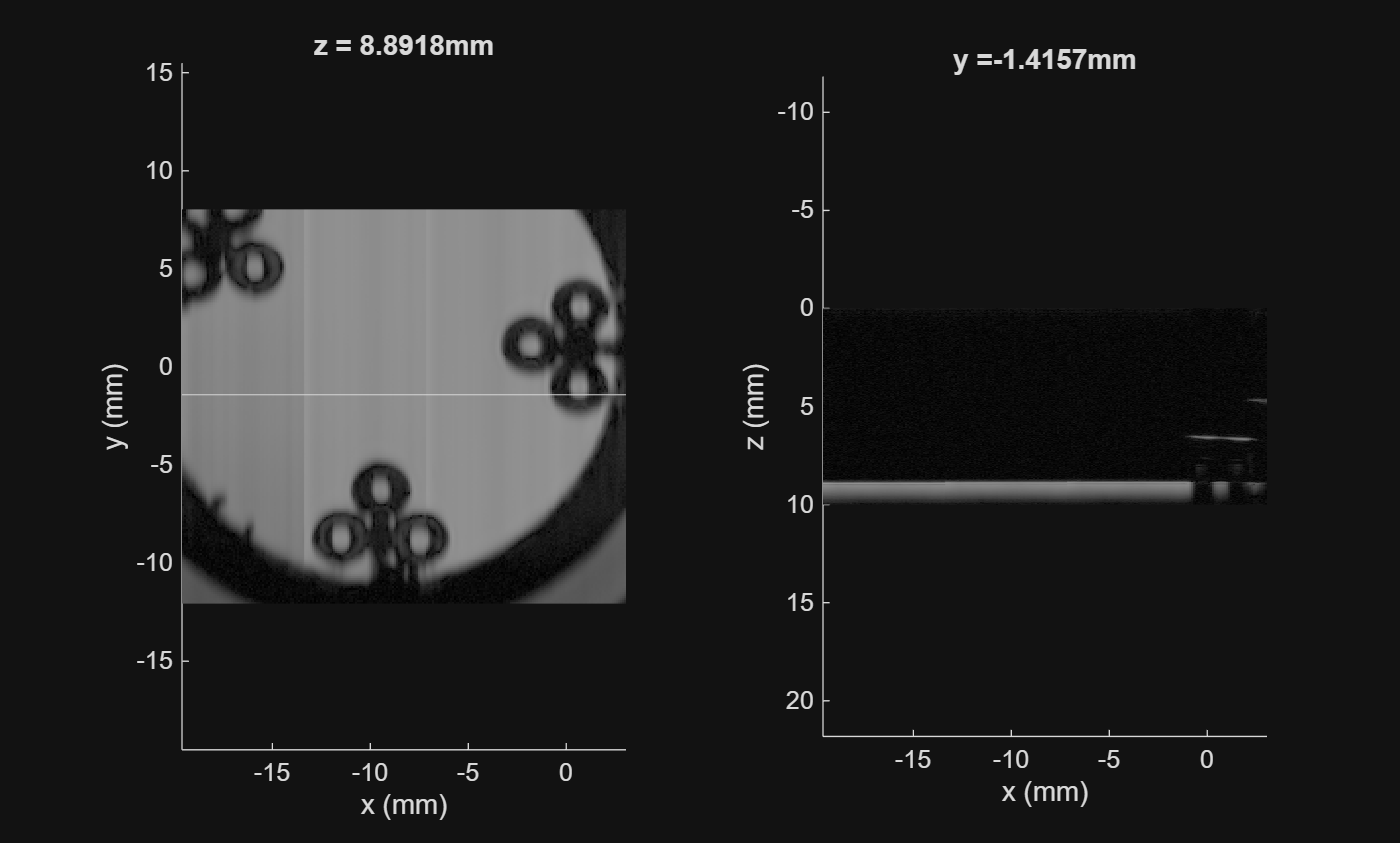

j = 107;
k = 752;
dynamic_range = [0 80];
% figure()
figure();tiledlayout(1,2);nexttile;
hold on
for l=1:3
    imagesc(xs + pos{l}(1),ys1,(squeeze(data_cell{l}(:,:,k)).'),dynamic_range)
end
yline(ys1(j))
hold off
% imagesc(xs,zs(zmask),squeeze(data_cell{1}(:,j,:)).')
% xlim([-20 5])
colormap gray
axis equal
title(['z = ' num2str(zs1(k)) 'mm'])
xlabel('x (mm)')
ylabel('y (mm)')

nexttile
hold on
for l=1:3
    imagesc(xs + pos{l}(1),(zs(zmask)),(squeeze(data_cell{l}(:,j,:)).'),dynamic_range)
end
set(gca, 'YDir', 'reverse');
hold off
title(['y =' num2str(ys1(j)) 'mm'])
xlabel('x (mm)')
ylabel('z (mm)')
axis equal
colormap gray

% end

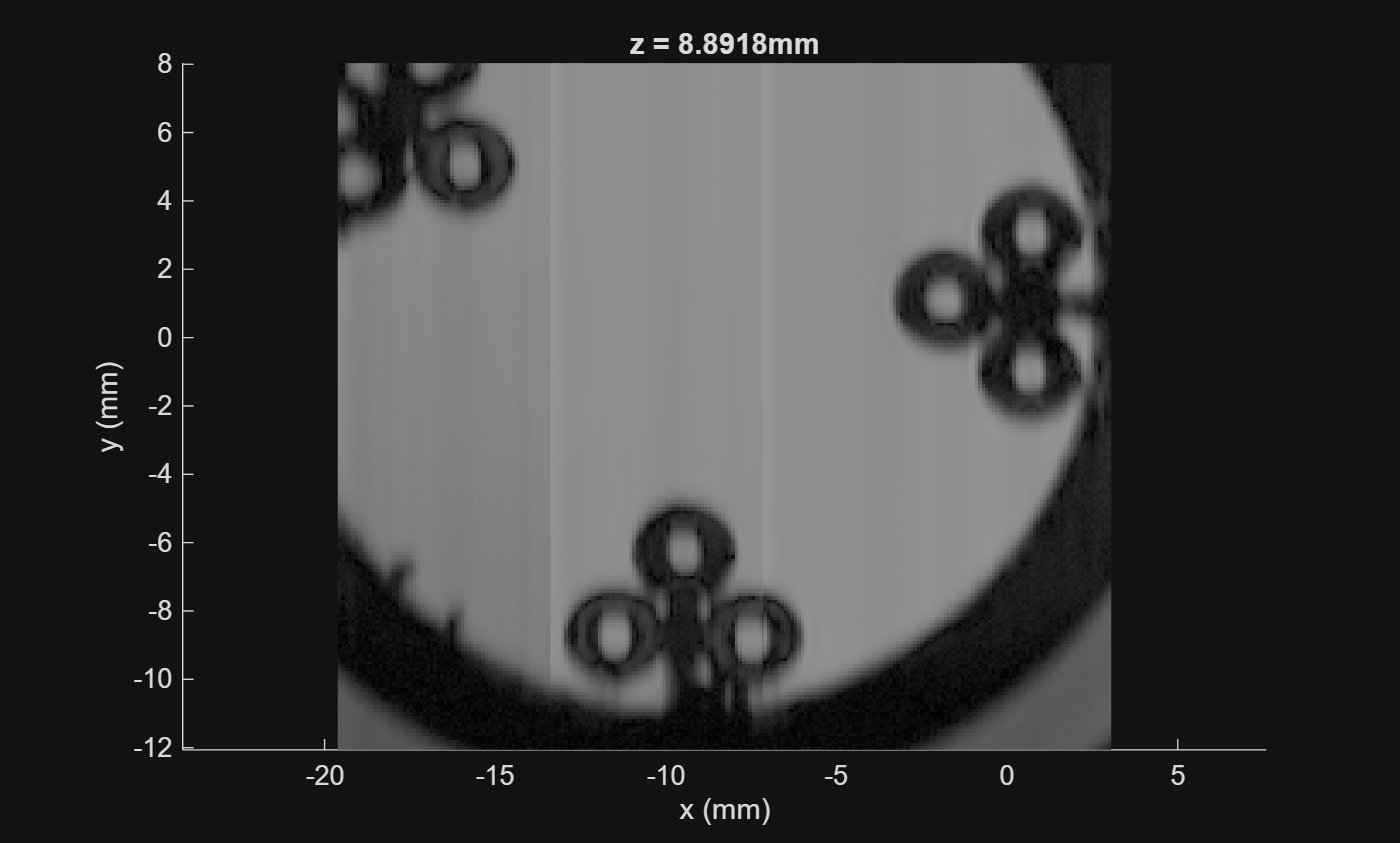

j = 107;
k = 752;
dynamic_range = [0 80];
figure()
% figure();tiledlayout(1,2);nexttile;
hold on
for l=1:3
    imagesc(xs + pos{l}(1),ys1,(squeeze(data_cell{l}(:,:,k)).'),dynamic_range)
end
% yline(ys1(j))
hold off
% imagesc(xs,zs(zmask),squeeze(data_cell{1}(:,j,:)).')
% xlim([-20 5])
colormap gray
axis equal
title(['z = ' num2str(zs1(k)) 'mm'])
xlabel('x (mm)')
ylabel('y (mm)')

topleftshg = [-16.2 4.467];
topleftus = [-16.36 5.5];
bottomshg = [-9.22 -6.5];
bottomus = [-9.5 -5.5];

%need to make a transform from SHG coordinates to US;
x_transform = @(x) 0.98*x - 0.4840;
y_transform = @(y) 1.0030*y + 1.0196;
